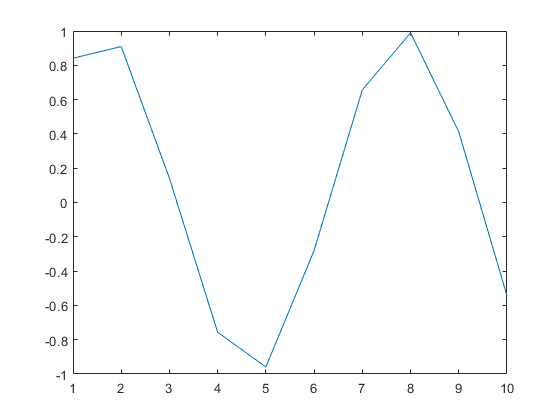

import mlreportgen.dom.*;

fig=figure;
figure(fig);
plot(1:1:10,sin(1:1:10));
exportgraphics(fig,'test.png','Resolution',300)


D=Document('Test','docx','WordReportTemplate')

D =   Document with properties:

           OutputPath: 'D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\MATLAB\EMVA1288\Report\Test'
          PackageType: 'zipped'
       ForceOverwrite: 1
         StreamOutput: 0
         TitleBarText: ''
          HTMLHeadExt: ''
         TemplatePath: 'WordReportTemplate'
                 Type: 'DOCX'
        CurrentHoleId: ''
      CurrentHoleType: ''
    CurrentPageLayout: []
           OpenStatus: 'unopened'
               Parent: []
             Children: [1×0 mlreportgen.dom.Node]
                  Tag: 'dom.Document:8292'
                   Id: '8292'


open(D)

ans = logical
   1


docHeaders = D.CurrentDOCXSection.PageHeaders

docHeaders =   DOCXPageHeader with properties:

             PageType: 'default'
         TemplateName: ''
         TemplatePath: 'D:\MATLAB\R2021a\toolbox\shared\mlreportgen\dom\resources\templates\docx\default.dotx'
                 Type: 'DOCX'
        CurrentHoleId: '#start#'
      CurrentHoleType: 'Block'
    CurrentPageLayout: []
           OpenStatus: 'open'
               Parent: []
             Children: [1×1 mlreportgen.dom.TemplateText]
                  Tag: 'dom.DOCXPageHeader:8438'
                   Id: '8438'


docFooters = D.CurrentDOCXSection.PageFooters

docFooters =   DOCXPageFooter with properties:

             PageType: 'default'
         TemplateName: ''
         TemplatePath: 'D:\MATLAB\R2021a\toolbox\shared\mlreportgen\dom\resources\templates\docx\default.dotx'
                 Type: 'DOCX'
        CurrentHoleId: '#start#'
      CurrentHoleType: 'Block'
    CurrentPageLayout: []
           OpenStatus: 'open'
               Parent: []
             Children: [1×1 mlreportgen.dom.TemplateText]
                  Tag: 'dom.DOCXPageFooter:8440'
                   Id: '8440'


docHead1=docHeaders(1)

docHead1 =   DOCXPageHeader with properties:

             PageType: 'default'
         TemplateName: ''
         TemplatePath: 'D:\MATLAB\R2021a\toolbox\shared\mlreportgen\dom\resources\templates\docx\default.dotx'
                 Type: 'DOCX'
        CurrentHoleId: '#start#'
      CurrentHoleType: 'Block'
    CurrentPageLayout: []
           OpenStatus: 'open'
               Parent: []
             Children: [1×1 mlreportgen.dom.TemplateText]
                  Tag: 'dom.DOCXPageHeader:8438'
                   Id: '8438'


docID=docHead1.moveToNextHole

docID = 'camera name'

while ~strcmp(D.CurrentHoleId,'#end#')
    D.CurrentHoleId
          if D.CurrentHoleId=="vendor"
              append(D,'vendor name');
          elseif D.CurrentHoleId=="resolution"
              append(D,12);
          elseif D.CurrentHoleId=="irradiation calibration accuracy"
              append(D,'keine');
          elseif D.CurrentHoleId=="plot1"
%               chap = mlreportgen.report.Chapter;
%               chap.add(fig);
%               append(D,chap);
              plot1=Image('test.png');
              plot1.Height="15cm";
              plot1.Width="16cm";
              append(D,plot1);
          end
          moveToNextHole(D);
end

ans = '#start#'

ans = '#sect2#'

ans = 'vendor'

ans = 'model'

ans = 'data type'

ans = 'sensor type'

ans = 'diagonal'

ans = 'lens category'

ans = 'resolution'

ans = 'pixel size'

ans = 'maximum readout rate'

ans = 'dark current compensation'

ans = 'interface type'

ans = 'light source'

ans = 'light source non uniformity'

ans = 'irradiation calibration accuracy'

ans = 'irradiation measurement error'

ans = 'standard version'

ans = '#sect3#'

ans = 'op_point'

ans = 'gain'

ans = 'black level'

ans = 'bit depth'

ans = 'illumination'

ans = 'irradiation steps'

ans = '#sect4#'

ans = 'gain op1'

ans = 'black level op1'

ans = 'bit depth op1'

ans = 'illumination op1'

ans = 'irradiation steps op1'

ans = '#sect5#'

ans = '#sect6#'

ans = 'quantum efficiency'

ans = 'sigma_d'

ans = 'sigma_y.dark'

ans = 'SNR_max'

ans = 'SNR_max dB'

ans = 'SNR_max bit'

ans = 'SNR_max_-1 percent'

ans = 'mu_p.min'

ans = 'mu_p.min.area'

ans = 'mu_e.min'

ans = 'mu_e.min.area'

ans = 'mu_p.sat'

ans = 'mu_p.sat.area'

ans = 'mu_e.sat'

ans = 'mu_e.sat.area'

ans = 'DR'

ans = 'DR dB'

ans = 'DR bit'

ans = 'DSNU e'

ans = 'DSNU DN'

ans = 'PRNU percent'

ans = 'LE_min'

ans = 'LE_max'

ans = 'mu_I.mean e/s'

ans = 'mu_I.mean DN/s'

ans = 'mu_I.var e/s'

ans = 'mu_I.var DN/s'

ans = '#sect7#'

ans = '#sect8#'

ans = 'photon transfer'

ans = 'signal-to-noise ratio'

ans = 'sensitivity'

ans = 'exposure time'

ans = 'linearity'

ans = 'deviation linearity'

ans = 'horizontal spectrogram prnu'

ans = 'horizontal spectrogram dsnu'

ans = 'vertical spectrogram prnu'

ans = 'vertical spectrogram dsnu'

ans = 'log hist dsnu'

ans = 'log hist prnu'

ans = 'acc log hist dsnu'

ans = 'acc log hist prnu'

ans = 'horizontal profiles'

ans = 'vertical profiles'

close(D)

ans = logical
   1
